### Introduction

### **Equations**

**Governing Equation**

The governing partial differential equation from Hostetler and Bartlein (1990) for the one-dimensional model is as follows:


$$\frac{\partial T}{\partial t}=\frac{1}{A\left(z\right)}\frac{\partial }{\partial z}\left\lbrace A\left(z\right)\left\lbrack \kappa_m +K\left(z,t\right)\right\rbrack \frac{\partial T}{\partial z}\right\rbrace +\frac{1}{A\left(z\right)}\frac{1}{c_w }\frac{\partial }{\partial z}\left(\Phi A\left(z\right)\right)$$


- Where T is water temperature (ºC)

- t is time (s)

- z is depth below the surface (m)

- κ_m is the molecular diffusivity of water (m^2 s^-1)

- K(z,t) is eddy diffusivity (m^2 s^-1)

- $c_w$ is the volumetric heat capacity of water (J m^-3 ºC^-1)

- Φ is a heat source term (W m^-2)

- A(z) is the surface area of the lake at depth z.

For the sake of a simplified model, we assumed that the heat source term and eddy diffusivity were negligible.  This simplifies the governing equation to the following partial differential equation:


$$\frac{\partial T}{\partial t}=\kappa_m \;\frac{\partial^2 T}{\partial z^2 }$$


$\kappa_m$ is the molecular diffusivity of water, which varies as a function of temperature. We calculated this term by taking values obtained in R. Mills (1973) and then using Excel to find a polynomial best-fit function. The function we obtained for this is:


$$\kappa_m =\left(16\ldotp 4-0\ldotp 151T_k +0\ldotp 000348T_k^2 \right){10}^{-9}$$


where T_k is the water temperature in degrees Kelvin.

#### Surface boundary condition

The surface boundary condition from Hostetler and Bartlein (1990) couples the governing equation of the model with the heat balance at the surface, and it is written as:


$$\left\lbrack \kappa_m +K\left(z,t\right)\right\rbrack \frac{\partial T}{\partial z}=K^* +L_d^* -L_u \pm Q_e \pm Q_h$$


- $K^*$ is net shortwave radiation at the water surface (W m^-2)

- $L_d^*$ is net longwave radiation from the atmosphere (W m^-2)

- $L_u$ is longwave radiation from the lake surface (W m^-2)

- $Q_e$ is flux of latent heat (W m^-2)

- $Q_h$ is flux of sensible heat (W m^-2)

Again, for our simplified model, the eddy diffusivity is neglected on the left-hand side. The right-hand side of this equation is the heat flux to the surface of the lake. K* represents the total incoming shortwave radiation from the sun at the lake surface. This value varies throughout the year on a seasonal cycle. We modeled this term as a sine function with a period of one year (units seconds). This equation is based on data gathered from maps published by the National Renewable Energy Labs (NREL) and assumes an incoming solar radiation of 500 W m^-2 on average, increasing by 100 W m^-2 in summer and decreasing by 100 W m^-2 in winter.


$$K^* =500+100\;\mathrm{sin}\left(\frac{2\pi t}{365*86400}\right)$$


The value of $K^*$ over a three-year period is calculated by the code below and is shown in the associated graph:

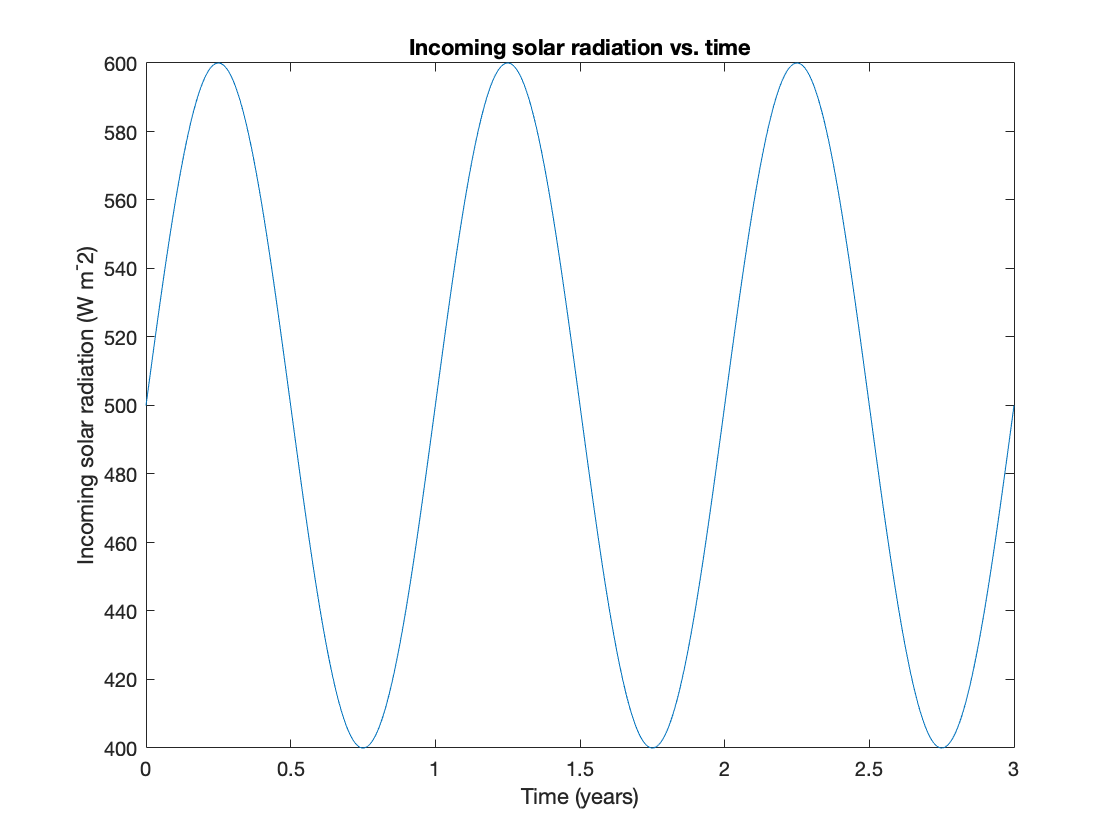

Kstar = @(t) 500+100*sin(2*pi*t/(365*86400));

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;
figure(10)
plot(ts/86400/365, Kstar(ts))
title('Incoming solar radiation vs. time')
xlabel('Time (years)')
ylabel('Incoming solar radiation (W m^-2)')

The outgoing longwave radiation term accounts for heat emitted from the lake surface, and is defined as follows:


$$L_u =\varepsilon \sigma T_k^4$$


where epsilon represents emissivity and is assumed to be constant at 0.97, sigma is the Stefan-Boltzmann constant (5.67 x 10^-8 W m^-2 K^-4), and $T_k$ is the temperature in degrees Kelvin. For the purposes of this simplified model, the temperature is assumed to be constant at 8ºC, the annual average temperature in the vicinity of Harney Lake. In reality, this value will fluctuate slightly over the course of a year.

The three other terms on the right-hand side of this equation, representing the flux of longwave radiation from the atmosphere and the fluxes of latent and sensible heat, are assumed to be zero.

With these assumptions, the surface boundary condition of our simplified model is the following Neumann boundary condition:


$$\kappa_m \frac{\partial T}{\partial z}=K^* -L_u$$


#### Bottom boundary condition for insulated lake bottom

According to Hostetler and Bartlein, if a lake is sufficiently deep or turbid, heat is not transferred between the water and the lake seiments beneath. As a result, the bottom boundary condition is:


$$\left\lbrack \kappa_m +K\left(z,t\right)\right\rbrack \frac{\partial T}{\partial z}=0$$


Again, eddy diffusivity was neglected in our simplified model, giving us the following zero flux Neumann boundary condition:


$$\kappa_m \frac{\partial T}{\partial z}=0$$


### Numerical Methods

We used the forward Euler method to simulate temperature diffusion through the lake. This method uses multiple known values at one time step to calculate each value at the next. We chose the forward Euler method as it is relatively simple to calculate and provided reliable results over our desired range. The marching equation for this method is:


$$T_i^{k+1} =T_i^k +C_D \left(T_{i-1}^k -2T_i^k +T_{i-1}^k \right)$$


where $C_D =D\frac{\Delta t}{\Delta z^2 }$ and is known as the diffusion number. The Forward Euler numerical method is stable as long as this value is less than or equal to 0.5.

For this model, we assumed the lake started out with a temperature of 8ºC at all depths, as this is approximately the annual average temperature at Harney Lake. Since the lake is very shallow with a depth of only 1 m, the model was run with a depth step of 0.1 m from 0 to 1 m. For time, the model was run with a time step of one day (86400 s) for a period of three years. This was done in order to show the expected pattern of seasonal variation.

#### Constant diffusivity, only bottom boundary condition  

Initially, we implemented the model with a constant diffusivity and only a bottom boundary condition. Our reasoning for this is we wanted to ensure a less complex version of the model ran and provided reliable results before we added a more complex boundary condition and a non-constant diffusivity term.

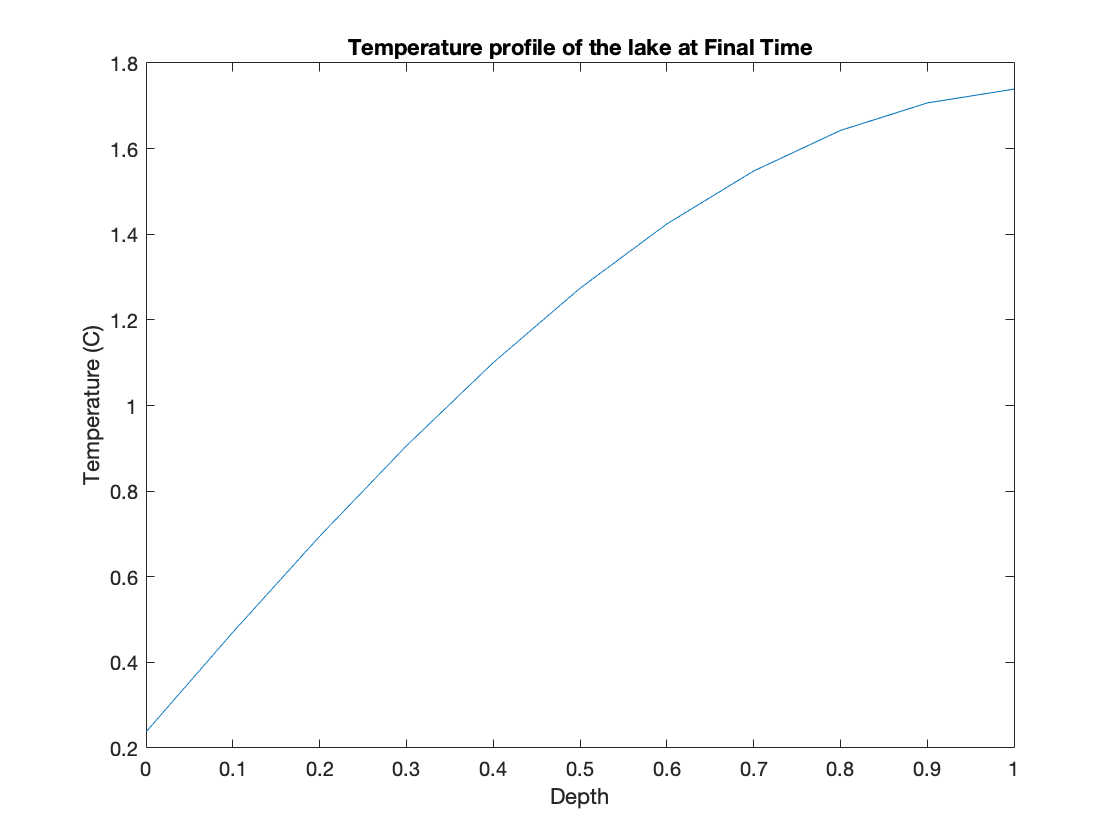

dz = 0.1; %depth grid spacing (m)
zf = 1; % lake depth in meters
zs = 0:dz:zf; % vector of depths in the lake

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;

D = 1e-8; %hard coded to something small enough that CD < 0.5

C_D = D*dt/(dz)^2;


% Forward Euler method

M = sparse(length(zs),length(zs));

% create matrix

for i = 1:length(zs)
    for j = 1:length(zs)
        if i==j
            M(i,j) = 1-2*C_D;
        elseif i-1==j
            M(i,j) = C_D;
        elseif i+1==j
            M(i,j) = C_D;
        end
    end
end


M(end,end-1)=C_D;
M(end,end) = 1-C_D;


% Pre-allocate

T_all = nan(length(zs), length(ts));
T = 8 .* ones(length(zs), 1); %initial T throughout lake is annual avg 8C
T_all(:,1) = T;

% Forward Euler Diffusion

for k = 1:length(ts)-1
    Tnew = M*T;
    
    T_all(:,k+1) = Tnew;
    T = Tnew;
end

% plot

figure(1);
plot(zs, T_all(:,length(ts))) % end
title('Temperature profile of the lake at Final Time')
xlabel('Depth')
ylabel('Temperature (C)')

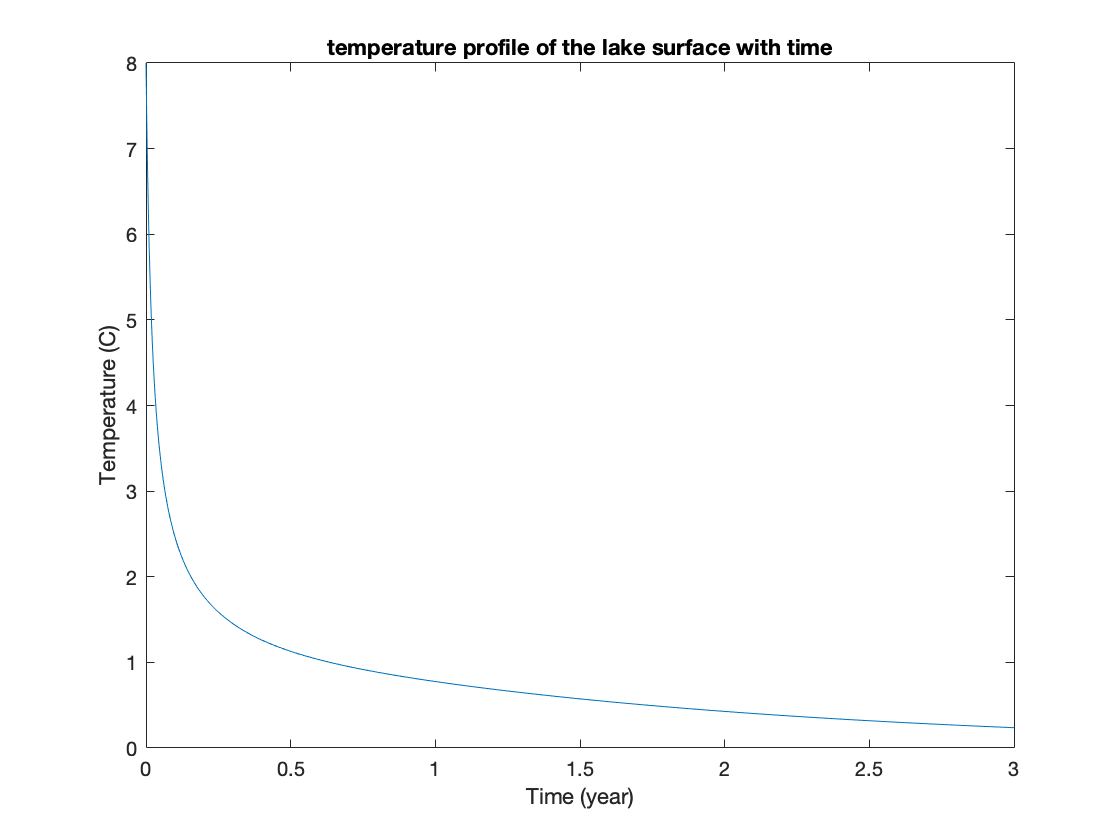


figure(2)
plot(ts/86400/365, T_all(1, :))
title('temperature profile of the lake surface with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

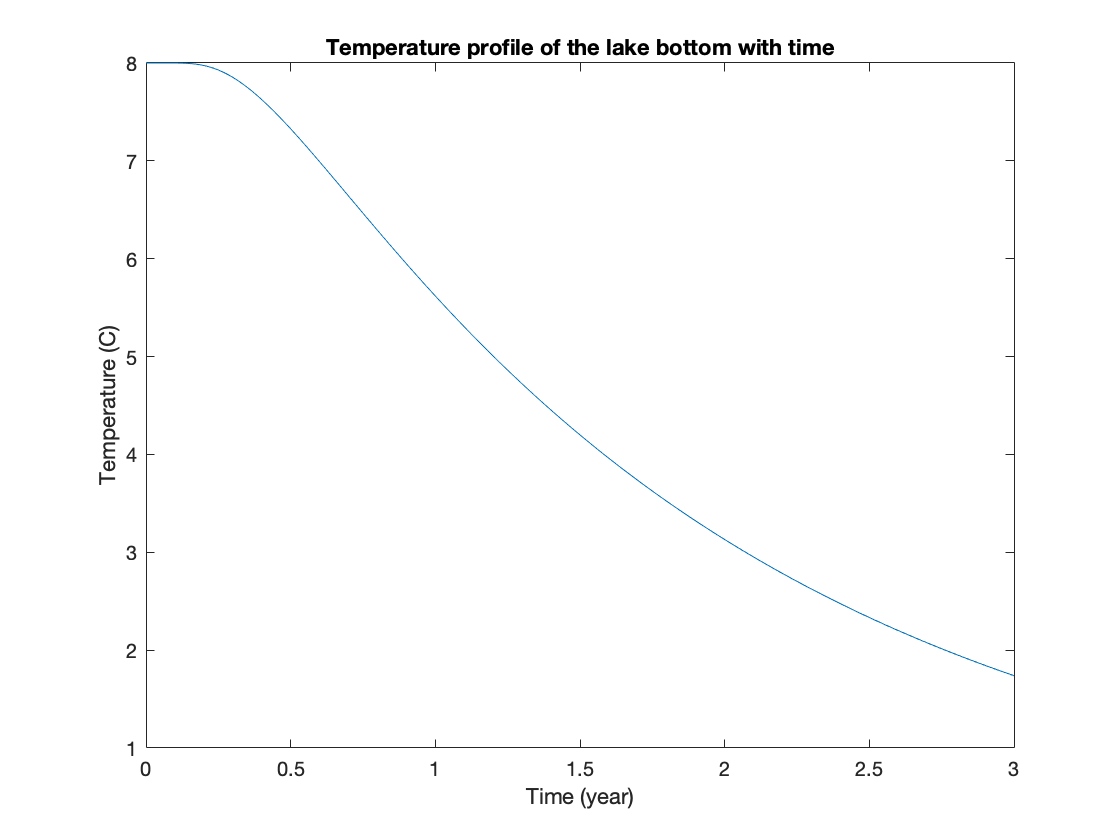


figure(3)
plot(ts/86400/365, T_all(end, :))
title('Temperature profile of the lake bottom with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

#### Constant diffusivity, both boundary conditions

Next, after seeing that the initial model worked successfully, we implemented a top boundary condition, which was somewhat complex as the surface heat flux is not constant in time. In addition, a conductivity calculation was necessary to convert surface heat flux into the surface value of temperature change with depth. The equation for this is:


$$\mathrm{Surface}\;\mathrm{heat}\;\mathrm{flux}=k\;\frac{\mathrm{dT}}{\mathrm{dz}}$$


where k is the thermal conductivity of water. This value varies with temperature, but for the purpose of this model it was set to a constant 575 W m^-1 K^-1, which is approximately the value of this quantity at 8ºC (American Society for Testing and Materials).

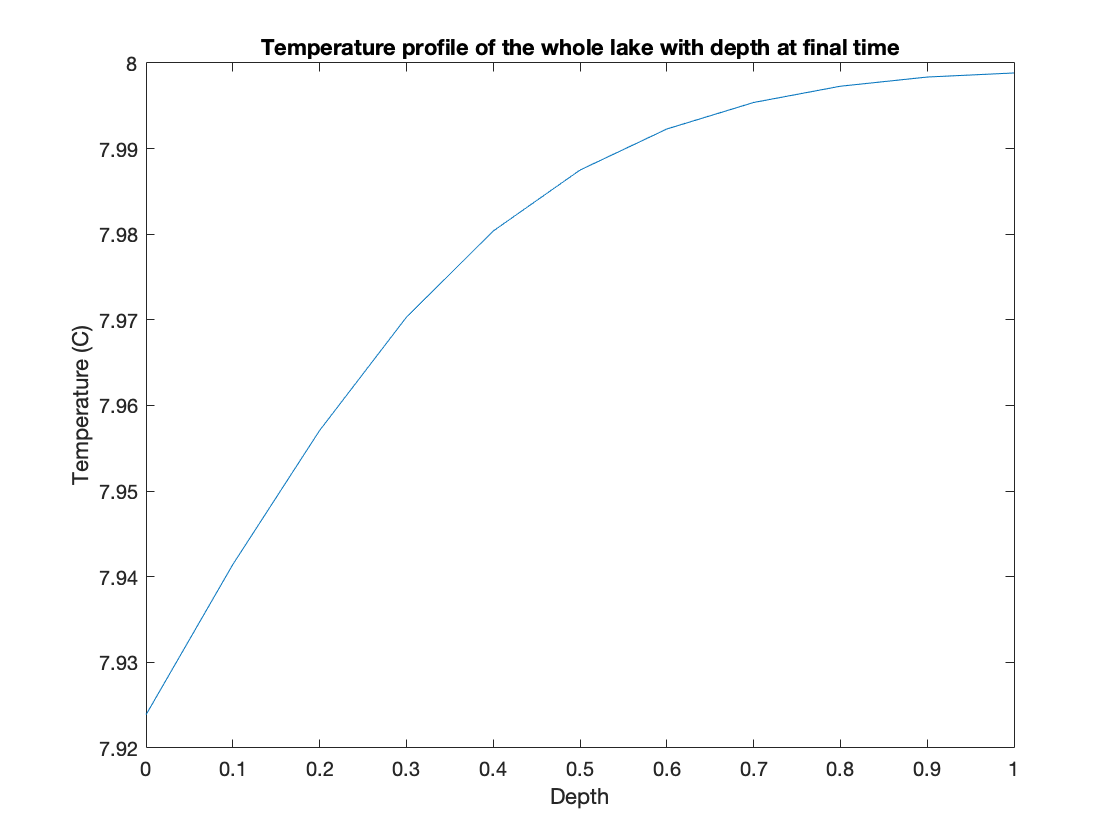

% Parameters and constants

dz = 0.1; %depth grid spacing (m)
zf = 1; % lake depth in meters
zs = 0:dz:zf; % vector of depths in the lake

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;

D = 1e-9; %hard coded to something small enough that CD < 0.5

C_D = D*dt/(dz)^2;

conductivity = 575; % W m^-1 K^-1 - slightly less than the value at 10C

% Net incoming shortwave radiation:

Kstar = @(t) 500+100*sin(2*pi*t/(365*86400));
% assume all radiation absorbed is right at the surface: e^(eta*z)=0

% Net longwave radiation:
epsilon = 0.97;
sigma = 5.67e-8;
% assume longwave radiation out with constant temp 8C
L_u = epsilon*sigma* (8 + 273.15)^4;

% Assume flux of sensible and latent heat are zero
Q_e = 0;
Q_h = 0;

%Total heat balance
heat = @(t) Kstar(t) - L_u + Q_e + Q_h;

% Forward Euler method

M = sparse(length(zs),length(zs));

% create matrix

for i = 1:length(zs)
    for j = 1:length(zs)
        if i==j
            M(i,j) = 1-2*C_D;
        elseif i-1==j
            M(i,j) = C_D;
        elseif i+1==j
            M(i,j) = C_D;
        end
    end
end

M(1,1) = 1-C_D;
M(1,2) = C_D;
M(end,end-1)=C_D;
M(end,end) = 1-C_D;


% Pre-allocate

T = 8 .* ones(length(zs), 1); %initial T throughout lake is annual avg 8C

T_all = nan(length(zs), length(ts));
T_all(:,1) = T;

known_vec = zeros(length(zs), 1);

% Forward Euler Diffusion

for k = 1:length(ts)-1
    
    F_sfc = heat(ts(k))/conductivity;
    
    known_vec(1) = -C_D*dz*F_sfc;
    
    Tnew = M*T + known_vec;
    
    T_all(:,k+1) = Tnew;
    T = Tnew;
end

% plot

figure(4);
plot(zs, T_all(:,length(ts))) % end
title('Temperature profile of the whole lake with depth at final time')
xlabel('Depth')
ylabel('Temperature (C)')

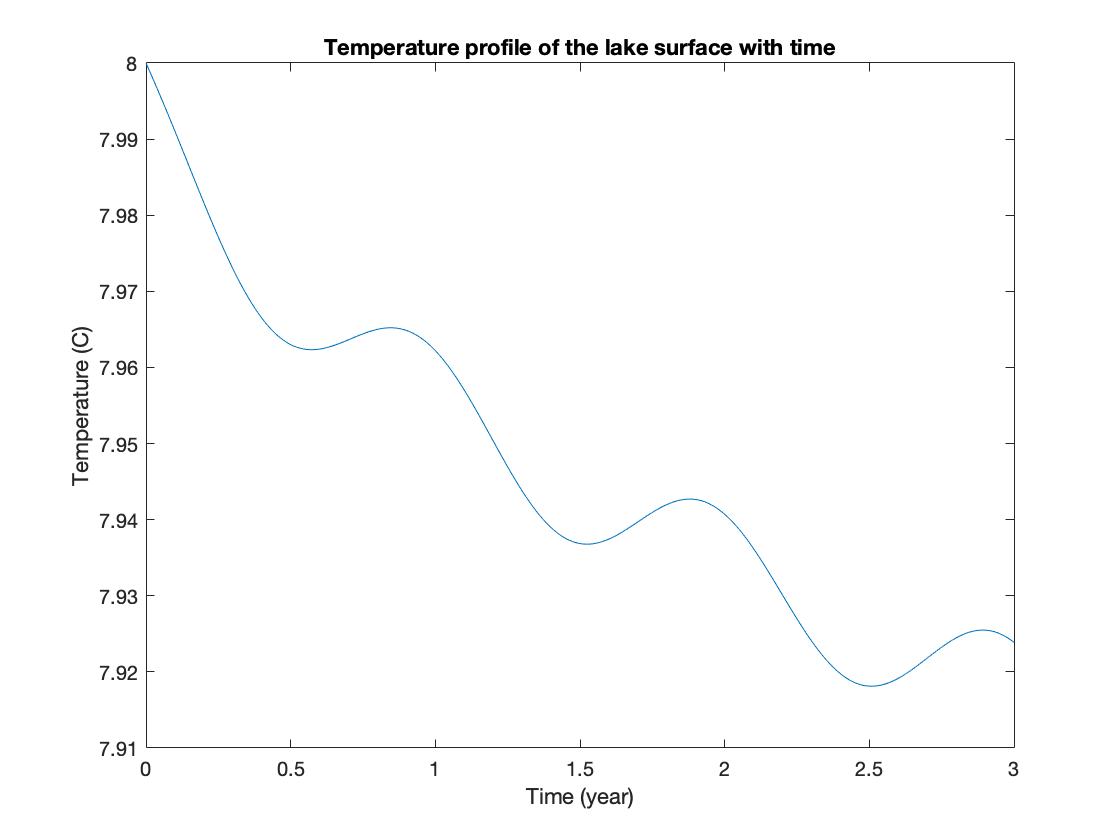


figure(5)
plot(ts/86400/365, T_all(1, :))
title('Temperature profile of the lake surface with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

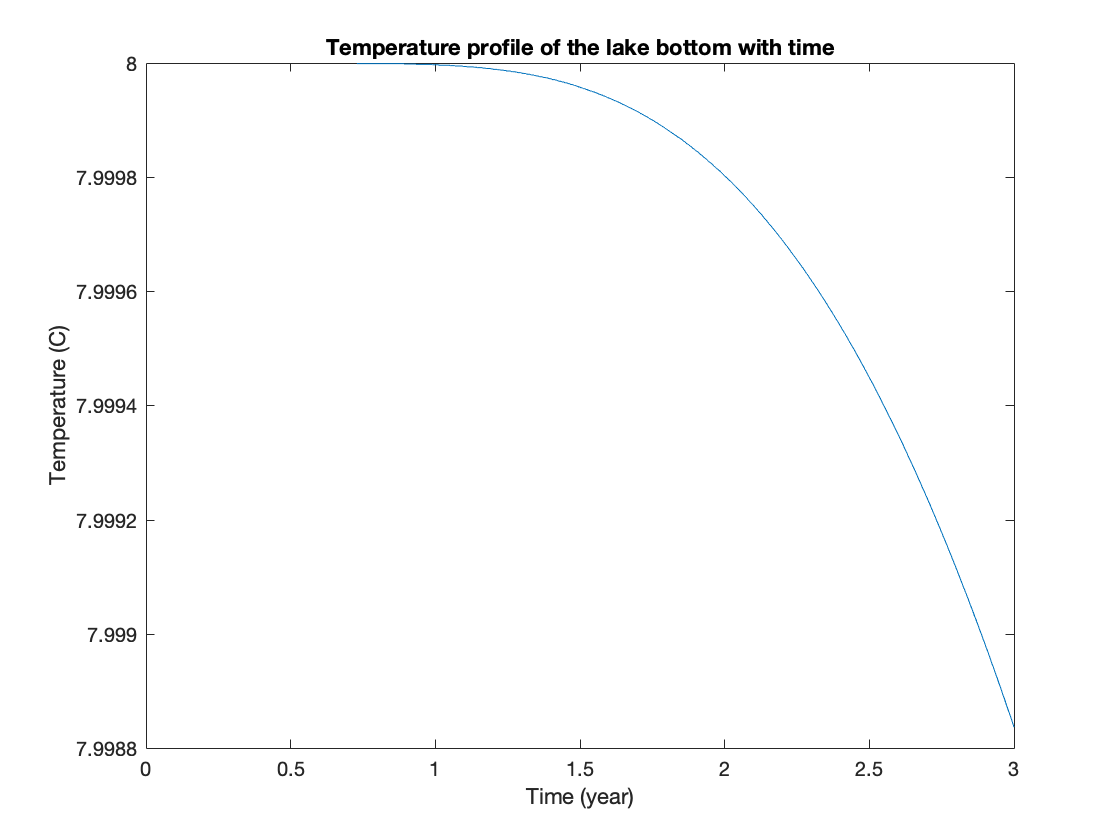


figure(6)
plot(ts/86400/365, T_all(end, :))
title('Temperature profile of the lake bottom with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

#### Varying diffusivity, both boundary conditions

After seeing acceptable results from this model, we implemented the non-constant diffusivity that changed with each iteration through our model.

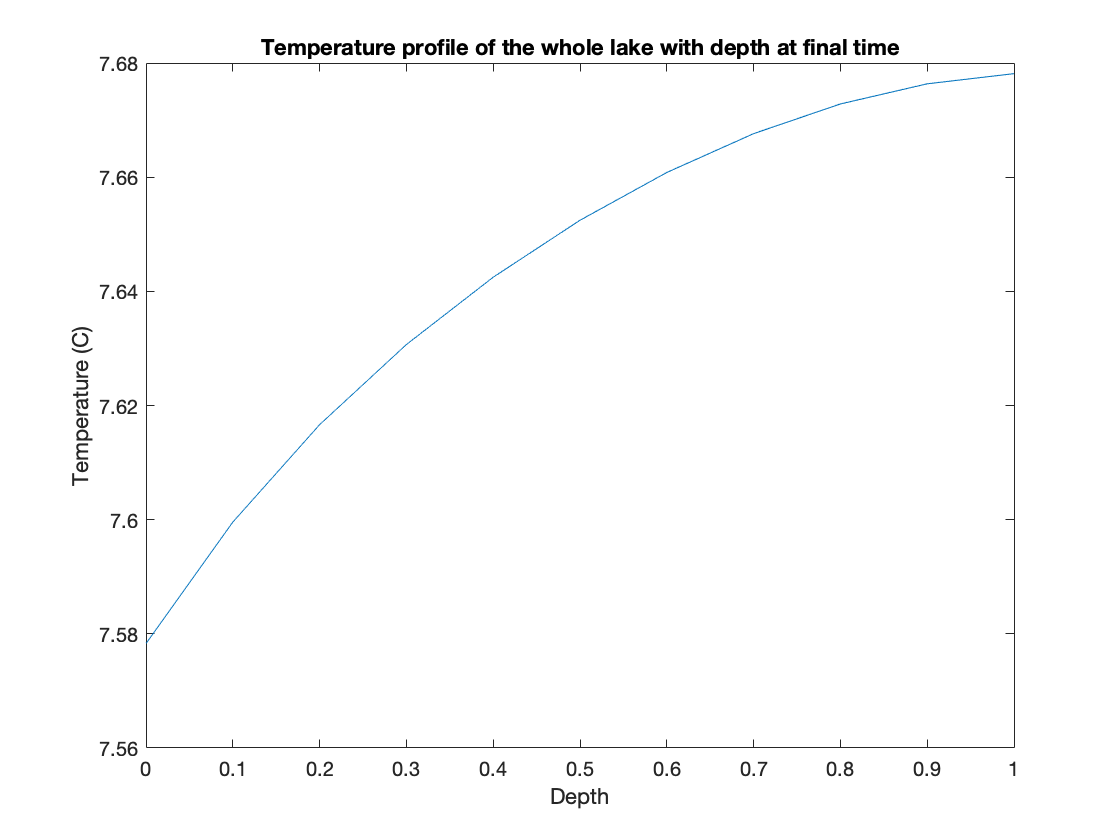


% Equation caluculated in Google Sheets from values in R. Mills (1973)

kappa_m = @(T_k) (16.4 - 0.151*T_k + 3.48e-4*T_k^2)*1e-9;

%% Parameters and constants

dz = 0.1; %depth grid spacing (m)
zf = 1; % lake depth in meters
zs = 0:dz:zf; % vector of depths in the lake

dt = 86400; % time grid spacing = 1 day
tf = 3600*24*365*3; % 3 years
ts = 0:dt:tf;

conductivity = 575; % W m^-1 K^-1 - slightly less than the value at 10C

% Net incoming shortwave radiation:

Kstar = @(t) 500+100*sin(2*pi*t/(365*86400));
% assume all radiation absorbed is right at the surface: e^(eta*z)=0

% Net longwave radiation:
epsilon = 0.97;
sigma = 5.67e-8;
% assume longwave radiation out with constant temp 8C
L_u = epsilon*sigma* (8 + 273.15)^4;

% Assume flux of sensible and latent heat are zero
Q_e = 0;
Q_h = 0;

%Total heat balance
heat = @(t) Kstar(t) - L_u + Q_e + Q_h;

%% Pre-allocate

T = 8 .* ones(length(zs), 1); %initial T throughout lake is annual avg 8C

T_all = nan(length(zs), length(ts));
T_all(:,1) = T;

known_vec = zeros(length(zs), 1);

%% Loop

for k = 1:length(ts)-1

    D = kappa_m(T(1));

    C_D = D*dt/(dz)^2;

    % Forward Euler method

    M = sparse(length(zs),length(zs));

    % create matrix

    for i = 1:length(zs)
        for j = 1:length(zs)
            if i==j
                M(i,j) = 1-2*C_D;
            elseif i-1==j
                M(i,j) = C_D;
            elseif i+1==j
                M(i,j) = C_D;
            end
        end
    end

    M(1,1) = 1-C_D;
    M(1,2) = C_D;
    M(end,end-1)=C_D;
    M(end,end) = 1-C_D;

    % Forward Euler Diffusion
    
    F_sfc = heat(ts(k))/conductivity;
    
    known_vec(1) = -C_D*dz*F_sfc;
    
    Tnew = M*T + known_vec;
    
    T_all(:,k+1) = Tnew;
    T = Tnew;
end

% plot

figure(7);
plot(zs, T_all(:,length(ts))) % end
title('Temperature profile of the whole lake with depth at final time')
xlabel('Depth')
ylabel('Temperature (C)')

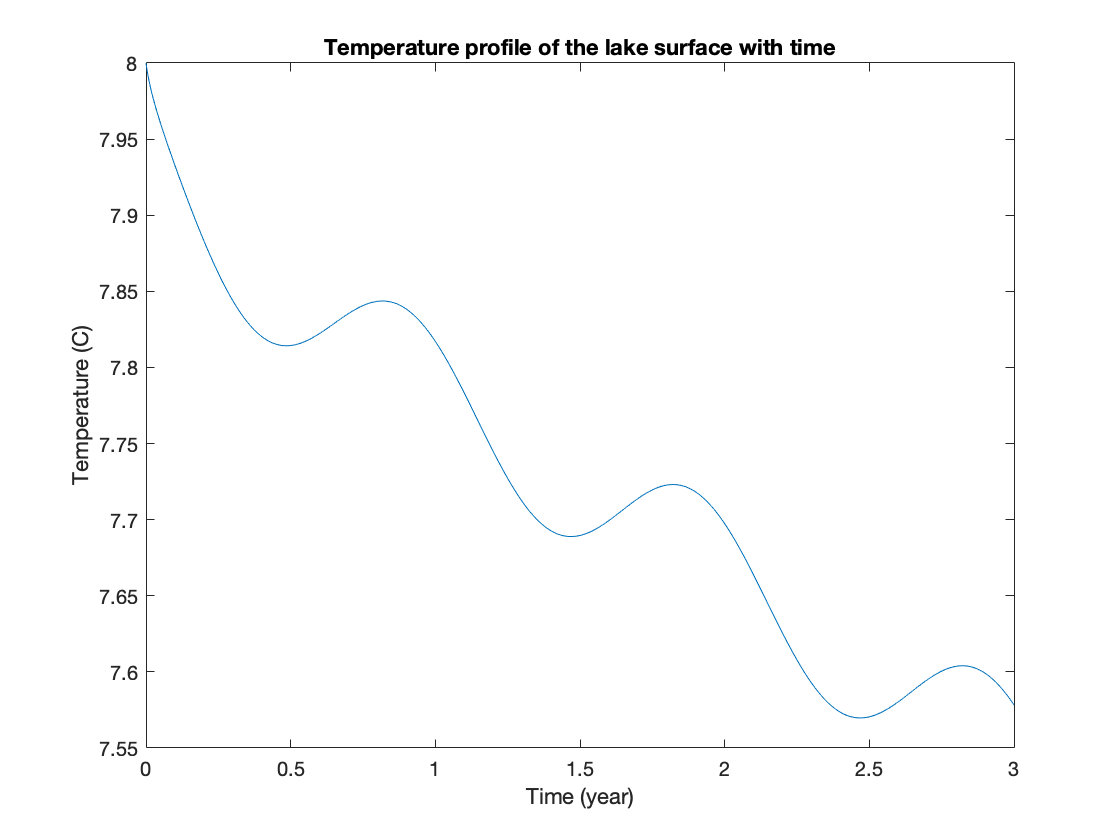


figure(8)
plot(ts/86400/365, T_all(1, :))
title('Temperature profile of the lake surface with time')
xlabel('Time (year)')
ylabel('Temperature (C)')

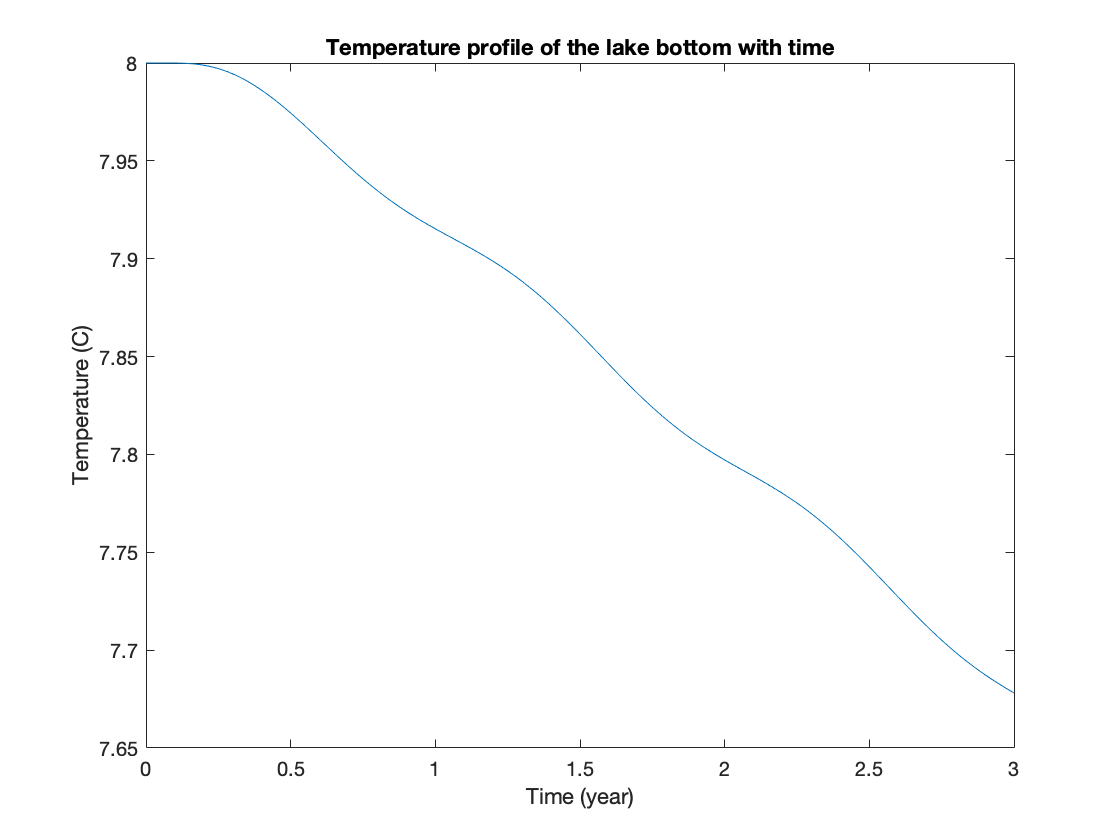


figure(9)
plot(ts/86400/365, T_all(end, :))
title('Temperature profile of the lake bottom with time')
xlabel('Time (year)')
Final model (non-constant diffusivity, both boundary conditions)
ylabel('Temperature (C)')

### Results

#### Initial model (constant diffusivity, bottom boundary condition only)

In this run, diffusivity was set to 1e-9, a value small enough to ensure the forward Euler method was stable. The only boundary condition set was the bottom, zero-flux Neumann condition. Again, this was for simplicity purposes and to make sure we had a working model before more complex conditions were implemented.

Figure 1 shows that at the conclusion of the model run, the temperature of the lake increases with depth. This makes sense as the only boundary condition accounted for is the insulated lake bottom. As a result, there is simply diffusion out of the top of the lake. This accounts for the low lake temperatures near or below 1ºC observed in this run. 

Figure 2 illustrates the changes in temperature of the lake surface over the 3-year time period. The temperature begins at the set 8ºC value, but drops off rapidly at the beginning before decreasing at a slower rate towards the end. This is an expected result because of the presence of only one boundary condition at the bottom, so nothing stops diffusion out of the top of the lake. Figure 3 is similar, but it illustrates the temperature at the lake bottom instead. Here, the temperature starts out roughly constant at the set 8ºC before beginning a decrease. Again, this is expected as there is only the bottom boundary condition. Initially, the temperature is nearly constant, but then begins to decrease as heat diffuses out the top of the lake.

#### Second model (constant diffusivity, both boundary conditions)

In this run, diffusivity was still set to a constant 1e-9. However, in addition to the bottom boundary condition, the top boundary condition relating temperature change at the lake surface to surface heat flux was implemented.

Figure 4, showing the change in lake temperature with depth at the end of the model run, depicts a similar image to figure 1, though several components of the temperature profile change. With the addition of the top boundary condition in our model, temperature still increases with depth, but at a slower rate.

The modeled temperature of the lake surface with time is shown in figure 5. The temperature varies with time through the course of a year, which is associated with the seasonal cycle of surface heat flux. However, there is overall a decreasing trend with time. Figure 6 illustrates the temperature over time at the lake bottom. Here, the temperature stays nearly constant at 8ºC for a much longer time period before beginning a very slow decrease due to the presence of the top boundary condition.

These results are not quite what we had expected. We expected the seasonal variation to cause a cycle where the lake surface temperature returned to its original value after one year. Instead, there is a small seasonal trend, and the lake temperature decreases overall every year, which is unrealistic. In addition, we expected the lake bottom temperature to experience a small variation over the entirety of the model run, with perhaps a seasonal cycle. However, it experienced a very slow decrease in this model. We expect this is due to some assumptions made or terms neglected in the process of simplifying the equations of the original model.

#### Final model (non-constant diffusivity, both boundary conditions)

In this run, both boundary conditions were implemented, and we used a non-constant diffusivity which changed on each iteration. 

Figure 7, like figures 1 and 4, illustrates the temperature profile of the whole lake at the conclusion of the model run and shows a similar pattern, with temperature increasing with depth. The lake surface temperature variation with time is shown in figure 8, which shows a similar pattern as seen with the previous model run in figure 5. The same decreasing trend with smaller variation corresponding to the annual seasonal cycle can be seen. However, the overall decreasing trend is faster than in the previous model. 

The temperature profile of the lake bottom is shown in figure 9. Like previous versions of this model, the temperature decreases with time, although at a slightly faster rate. However, in this run, a slight seasonal component is observed, with the rate of decrease slowing at some times of the year and increasing at others.

Again, these results are not quite what we had expected, with both the lake surface temperature and lake bottom temperature still showing an overall decrease through time. However, with this version of the model, a slight seasonal variation can be seen in the lake bottom temperatures, which was not seen previously. Therefore, we believe this model is the most accurate of the three models we ran.

### Figures

See images in right column of MATLAB Live Script.

### Conclusions